# Number Section Headings, Table Titles, and Figure Captions Programmatically

This example shows how to programmatically create numbered headings for chapters and hierarchical numbered headings for subsections in a chapter. The example also demonstrates how to create hierarchical numbered table titles and figure captions that reside in a numbered chapter or a subsection in a chapter.

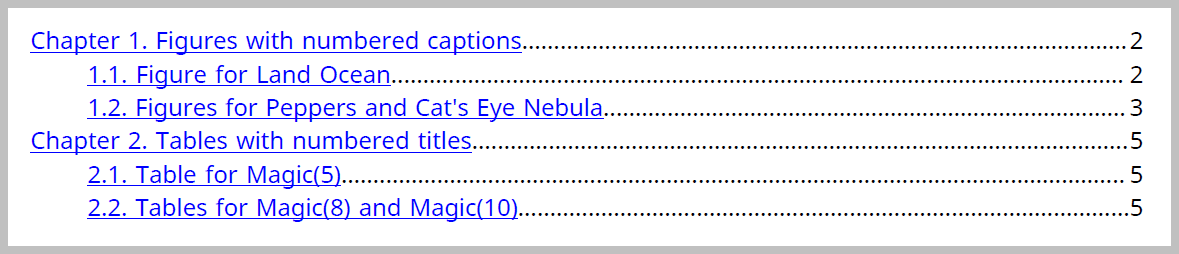

Import the DOM API package so you do not have to use long, fully-qualified class names.

import mlreportgen.dom.*

Create and open a document. To create a Word document, change the output type from `pdf` to `docx`. To create a HTML document, change `pdf` to `html` or `html-file` for a multifile or single-file document, respectively.

d = Document("mydoc","pdf");
open(d);

Append a table of contents to the document.

append(d,TOC);

Create numbering streams for chapter headings, subsection headings, figure captions, and table titles. By default, the streams are created using Arabic numbers with an initial value of `0`.

chapterStream = createAutoNumberStream(d,"chapter");
sectionStream = createAutoNumberStream(d,"section");
figureStream = createAutoNumberStream(d,"figure");
tableStream = createAutoNumberStream(d,"table");

Define some image, table, and table entries styles, which will be used in the later sections.

imageStyle = ...
    { ...
    Height("5in"), ...
    Width("5in") ...
    };

tableStyle = ...
    { ...
    Width("100%"), ...
    Border("solid"), ...
    RowSep("solid"), ...
    ColSep("solid") ...
    };

tableEntriesStyle = ...
    { ...
    HAlign("center"), ...
    VAlign("middle") ...
    };

The following code creates the first chapter in the document. The chapter title is created using the `getChapterTitle` function. This function uses the `chapter` numbering stream to create a numbered chapter title. The chapter consists of two subsections, whose titles are created using the `getSectionTitle` function. This function uses both `chapter` and `section` numbering streams to create the hierarchical numbered section title. The subsections consists of multiple figures with hierarchical numbered captions, which are created using the `getFigureCaption` function. This function uses both `chapter` and `figure` numbering streams to create the hierarchical numbered figure caption. The `getChapterTitle`, `getSectionTitle`, and `getFigureCaption` functions used to create this chapter are described later in this example.

% Chapter 1.
chapterTitle = getChapterTitle("Figures with numbered captions");
append(d,chapterTitle);

% Section 1.1.
sectionTitle = getSectionTitle("Figure for Land Ocean");
append(d,sectionTitle);

% Figure 1.1.
image1 =  Image(which("landOcean.jpg"));
image1.Style = imageStyle;
append(d,image1);
append(d,getFigureCaption("Land Ocean"));

% Section 1.2.
sectionTitle = getSectionTitle("Figures for Peppers and Cat's Eye Nebula");
append(d,sectionTitle);

% Figure 1.2.
image2 = Image(which("peppers.png"));
image2.Style = imageStyle;
append(d,image2);
append(d,getFigureCaption("Peppers"));

% Figure 1.3.
image3 = Image(which("ngc6543a.jpg"));
image3.Style = imageStyle;
append(d,image3);
append(d,getFigureCaption("Cat's Eye Nebula or NGC 6543"));

The following code creates the second chapter in the document. The chapter has a numbered title with two hierarchical numbered subsections. Here, the subsections consists of multiple tables with hierarchical numbered titles, which are created using the `getTableTitle` function, defined later in this example. This function uses both `chapter` and `table` numbering streams to create the hierarchical numbered table title.

% Chapter 2.
chapterTitle = getChapterTitle("Tables with numbered titles");
append(d,chapterTitle);

% Section 2.1.
sectionTitle = getSectionTitle("Table for Magic(5)");
append(d,sectionTitle);

% Table 2.1.
append(d,getTableTitle("Magic(5)"));
table1 = Table(magic(5));
table1.Style = tableStyle;
table1.TableEntriesStyle = tableEntriesStyle;
append(d,table1);

% Section 2.2.
sectionTitle = getSectionTitle("Tables for Magic(8) and Magic(10)");
append(d,sectionTitle);

% Table 2.2.
append(d,getTableTitle("Magic(8)"));
table2 = Table(magic(8));
table2.Style = tableStyle;
table2.TableEntriesStyle = tableEntriesStyle;
append(d,table2);

% Table 2.3.
append(d,getTableTitle("Magic(10)"));
table3 = Table(magic(10));
table3.Style = tableStyle;
table3.TableEntriesStyle = tableEntriesStyle;
append(d,table3);

Close and view the document.

close(d);
rptview(d);

The following function returns a numbered title for a chapter. The numbered title is created using the DOM `Heading1` object, where the title content is prefixed by a string `Chapter N` and a period, where `N` is the `chapter` stream counter. For example, the title for the first chapter contains "Chapter 1." as its prefix. The `CounterInc` format in the `Style` property causes the `chapter` stream counter to be incremented when this chapter title is appended to the document. The `CounterReset` format in the `Style` property causes the other associated stream counters such as, `section`, `figure`, and `table`, to be reset to their initial values when this chapter title is appended to the document.

function chapterTitle = getChapterTitle(content)
    import mlreportgen.dom.*
    
    chapterTitle = Heading1();
    append(chapterTitle,Text("Chapter "));
    append(chapterTitle,AutoNumber("chapter"));
    append(chapterTitle,Text(". "));
    append(chapterTitle,Text(content));
    
    chapterTitle.Style = ...
        { ...
        CounterInc("chapter"), ...
        CounterReset("section figure table"), ...
        WhiteSpace("preserve"), ...
        PageBreakBefore(true), ...
        KeepWithNext(true) ...
        };
end

The following function returns a hierarchical numbered title for a section that is in a chapter. The hierarchical numbered title is created using the DOM `Heading2` object, where the title content is prefixed by a string "N.M.", where N and M are the `chapter` and `section` stream counters, respectively. For example, the title for the first section in the second chapter contains "2.1" as its prefix. The `CounterInc` format in the `Style` property causes the `section` stream counter to be incremented when this section title is appended to the document.

function sectionTitle = getSectionTitle(content)
    import mlreportgen.dom.*
    
    sectionTitle = Heading2();
    append(sectionTitle,AutoNumber("chapter"));
    append(sectionTitle,Text("."));
    append(sectionTitle,AutoNumber("section"));
    append(sectionTitle,Text(". "));
    append(sectionTitle,Text(content));
    
    sectionTitle.Style = ...
        { ...
        CounterInc("section"), ...
        WhiteSpace("preserve"), ...
        KeepWithNext(true) ...
        };
end

The following function returns a hierarchical numbered caption for a figure added to a chapter or a subsection in a chapter. The hierarchical numbered caption is created using the DOM `Paragraph` object, where the caption content is prefixed by a string "Figure N.F.", where N and F are the `chapter` and `figure` stream counters, respectively. For example, the caption for the third figure in the second chapter contains "Figure 2.3." as its prefix. The `CounterInc` format in the `Style` property causes the `figure` stream counter to be incremented when this figure caption is appended to the document.

function figureCaption = getFigureCaption(content)
    import mlreportgen.dom.*
    
    figureCaption = Paragraph();
    append(figureCaption,Text("Figure "));
    append(figureCaption,AutoNumber("chapter"));
    append(figureCaption,Text("."));
    append(figureCaption,AutoNumber("figure"));
    append(figureCaption,Text(". "));
    append(figureCaption,Text(content));
    
    keepWithPrevious = FOProperty("keep-with-previous.within-page","always");
    figureCaption.Style = ...
        { ...
        CounterInc("figure"), ...
        WhiteSpace("preserve"), ...
        FOProperties(keepWithPrevious) ...
        };
end

The following function returns a hierarchical numbered title for a table added to a chapter or a subsection in a chapter. The hierarchical numbered title is created using the DOM `Paragraph` object, where the title content is prefixed by a string "Table N.T.", where `N` and `T` are the `chapter` and `table` stream counters, respectively. For example, the title for the third table in the second chapter contains "Table 2.3." as its prefix. The `CounterInc` format in the `Style` property causes the `table` stream counter to be incremented when this table title is appended to the document.

function tableTitle = getTableTitle(content)
    import mlreportgen.dom.*
    
    tableTitle = Paragraph();
    append(tableTitle,Text("Table "));
    append(tableTitle,AutoNumber("chapter"));
    append(tableTitle,Text("."));
    append(tableTitle,AutoNumber("table"));
    append(tableTitle,Text(". "));
    append(tableTitle,Text(content));
    
    tableTitle.Style = ...
        { ...
        CounterInc("table"), ...
        WhiteSpace("preserve"), ...
        KeepWithNext(true), ...
        Bold(true), ...
        OuterMargin("0pt", "0pt", "10pt", "5pt") ...
        };
end

*Copyright 2018 The MathWorks, Inc.*